# Example raster plots showing mean responses & the effect of shuffling

d = SessManager.load_special('Mouse2022', 'events_transients');

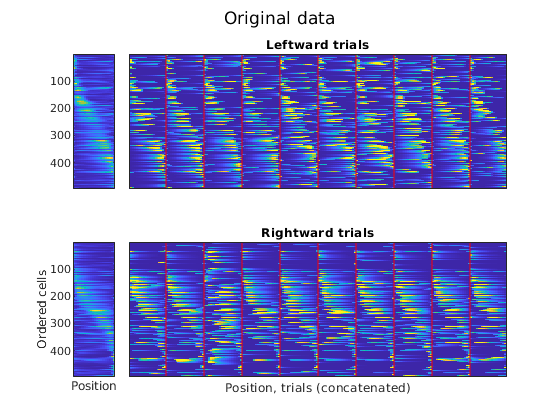

DecodeTensor.tensor_vis(d.data_tensor, d.tr_dir, @(x)x, 8);
sgtitle('Original data');
Utils.printto('events_figs/rasters', 'real_rasters.pdf');

T_shuf = DecodeTensor.shuffle_tensor_common(d.data_tensor, d.tr_dir);

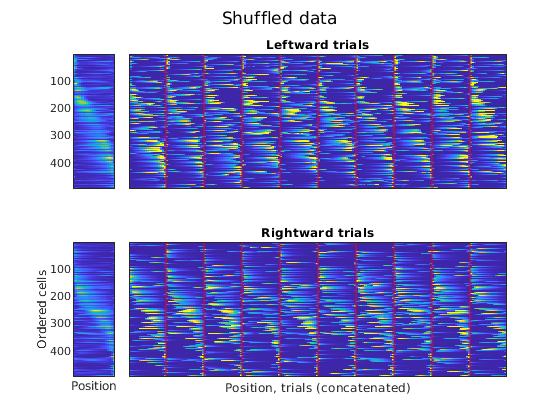

DecodeTensor.tensor_vis(T_shuf, d.tr_dir, @(x)x, 8);
sgtitle('Shuffled data');
Utils.printto('events_figs/rasters', 'shuf_rasters.pdf');

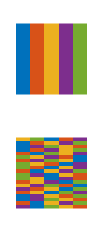

C = 5;
R = 20;
schematic_trials = (1:C) + zeros(R,1);
figure('Units',"inches", "Position",[0 0 1 2.5]);
subplot(2,1,1);
imagesc(schematic_trials);
colormap(lines(5));
set(gca, 'visible', 'off');
axis square

schematic_trials_shuf = schematic_trials;
old_rng = rng;
rng(0);
for i = 1:R
    schematic_trials_shuf(i, :) = schematic_trials_shuf(i, randperm(C));
end
rng(old_rng);
subplot(2,1,2);
imagesc(schematic_trials_shuf);
colormap(lines(5));
set(gca, 'visible', 'off');
axis square

right_tensor = d.data_tensor(:,:,d.tr_dir==1);
flatten = @(t) reshape(t, [size(t,1), size(t,2)*size(t,3)]);

right_meanact = mean(right_tensor, 3);

[~,b_] = max(right_meanact,[],2);
[~,o_right] = sort(b_);

right_meanact = right_meanact(o_right,:);
right_tensor = right_tensor(o_right,:,:);

T_shuf = DecodeTensor.shuffle_tensor_common(d.data_tensor, d.tr_dir);

right_tensor_shuf = T_shuf(:,:,d.tr_dir==1);
right_meanact_shuf = mean(right_tensor_shuf, 3);
[~,b_] = max(right_meanact_shuf,[],2);
[~,o_right_shuf] = sort(b_);
assert(isequal(o_right, o_right_shuf));
right_meanact_shuf = right_meanact_shuf(o_right, :);
right_tensor_shuf = right_tensor_shuf(o_right, :, :);


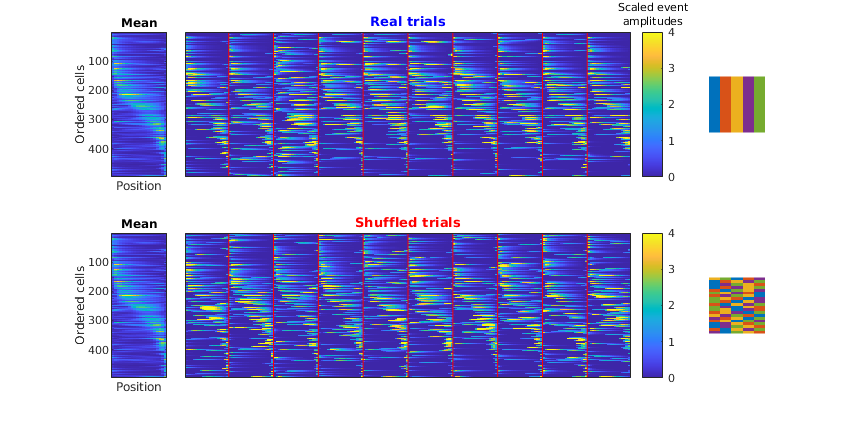

figure('Units', 'inches', 'Position', [26.1562    4.0312    8.8021    4.4271]);
w = 9;
sub_t = 10; start_at = 15;
clim = [0 4];

subplot(2,w,1 ); imagesc(right_meanact, clim); xlabel 'Position'; ylabel 'Ordered cells'; title 'Mean'
set(gca, 'XTick', []);
subplot(2,w,w+1); imagesc(right_meanact_shuf, clim); xlabel 'Position'; ylabel 'Ordered cells'; title 'Mean'
set(gca, 'XTick', []);

if w < 2
    return;
end
subplot(2,w,2:w-1); imagesc(flatten(right_tensor), clim);
xlim([1 sub_t*size(right_tensor,2)] + start_at*size(right_tensor,2));
title 'Real trials' 'Color' 'b'
for i = 1:sum(d.tr_dir == 1)
    hold on;
    l_ = line([20*i 20*i]+0.5, ylim);
    l_.Color = 'r';
end
set(gca, 'XTick', []);
set(gca, 'YTick', []);
h = colorbar;
title(h, sprintf('Scaled event\namplitudes'));

subplot(2,w,w+2:2*w-1); imagesc(flatten(right_tensor_shuf), clim);
xlim([1 sub_t*size(right_tensor_shuf,2)] + start_at*size(right_tensor_shuf,2));
title 'Shuffled trials' 'Color' 'r'
for i = 1:sum(d.tr_dir == 1)
    hold on;
    l_ = line([20*i 20*i]+0.5, ylim);
    l_.Color = 'r';
end
set(gca, 'XTick', []);
set(gca, 'YTick', []);
colorbar;


subplot(2,w,w);
imagesc(schematic_trials);
colormap(gca, lines(5));
set(gca, 'visible', 'off');
axis square

subplot(2,w,2*w);
imagesc(schematic_trials_shuf);
colormap(gca, lines(5));
set(gca, 'visible', 'off');
axis square
Utils.printto('events_figs/rasters', 'trial_shuffle_on_data.pdf');